close all
clear all
clc

## Sistema original (lazo abierto)

G = tf([0 0 0 16],[1 7.59 16 0])


G =
 
           16
  ---------------------
  s^3 + 7.59 s^2 + 16 s
 
Continuous-time transfer function.



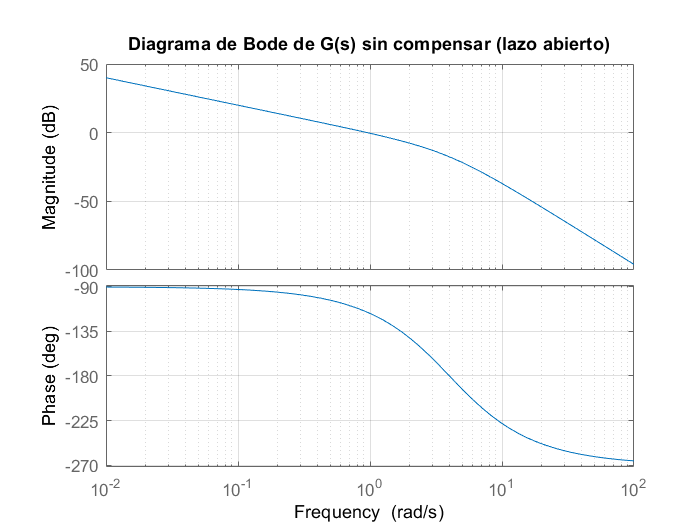

bode(G,{0.01 100})
title('Diagrama de Bode de G(s) sin compensar (lazo abierto)')
grid

## Controlador de atraso

kc = 5.66;
pc = -0.0035;
zc = -0.02;
C=zpk(zc, pc, kc)


C =
 
  5.66 (s+0.02)
  -------------
   (s+0.0035)
 
Continuous-time zero/pole/gain model.



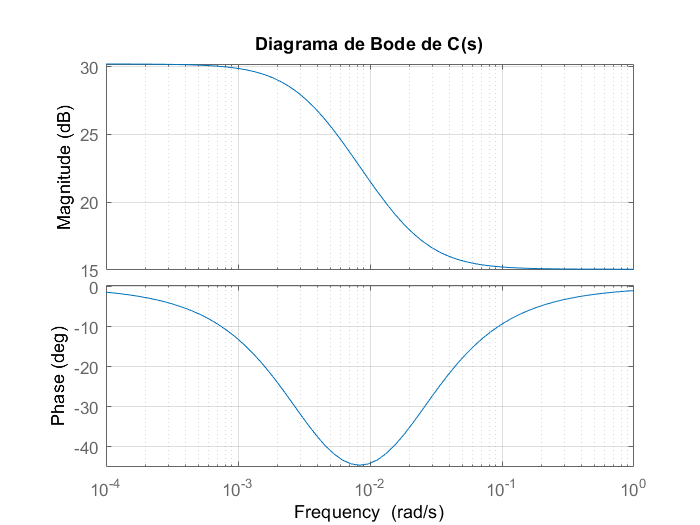

bode(C)
title('Diagrama de Bode de C(s)')
grid

## Sistema + controlador de atraso

sysC=G*C


sysC =
 
          90.56 (s+0.02)
  -------------------------------
  s (s+0.0035) (s^2 + 7.59s + 16)
 
Continuous-time zero/pole/gain model.



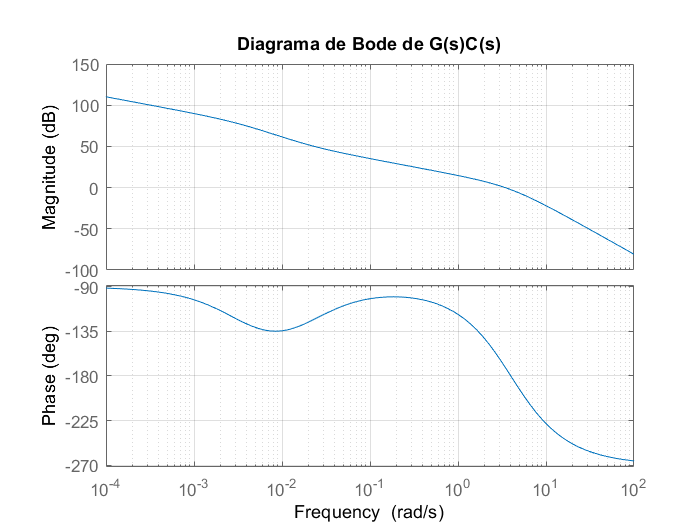

bode(sysC)
title('Diagrama de Bode de G(s)C(s)')
grid

## Comparación entre el sistema sin compensador y el sistema compensado

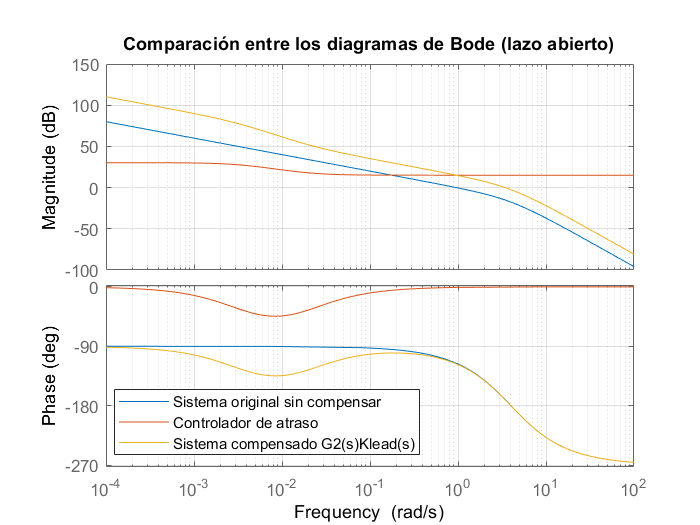

bode(G); hold on
bode(C); hold on
bode(sysC); hold on
legend('Sistema original sin compensar','Controlador de atraso','Sistema compensado G2(s)Klead(s)','location','best');
title('Comparación entre los diagramas de Bode (lazo abierto)')
grid

## Respuestas al escalón (sistema en lazo cerrado)

hold off;

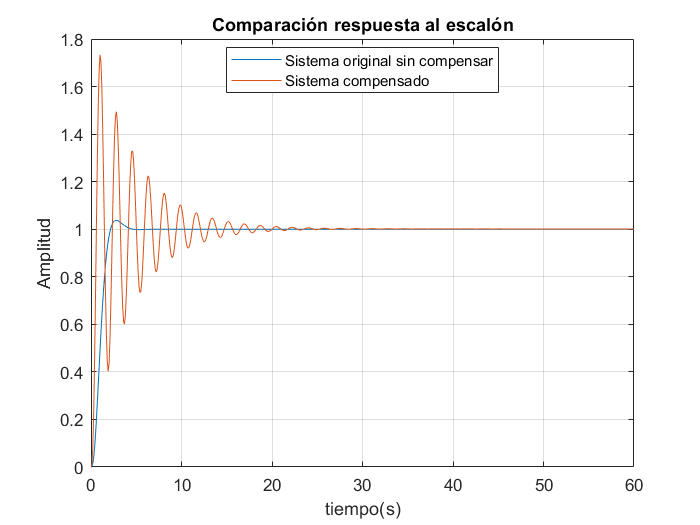

t=0:0.1:60;
fsys=feedback(G,1);
fsysC=feedback(sysC,1);
a = step(fsys,t);
b = step(fsysC,t);
plot(t,a,t,b)
legend('Sistema original sin compensar','Sistema compensado','location','best');
title('Comparación respuesta al escalón')
xlabel('tiempo(s)')
ylabel('Amplitud')
grid

## Respuestas a la rampa (sistema en lazo cerrado)

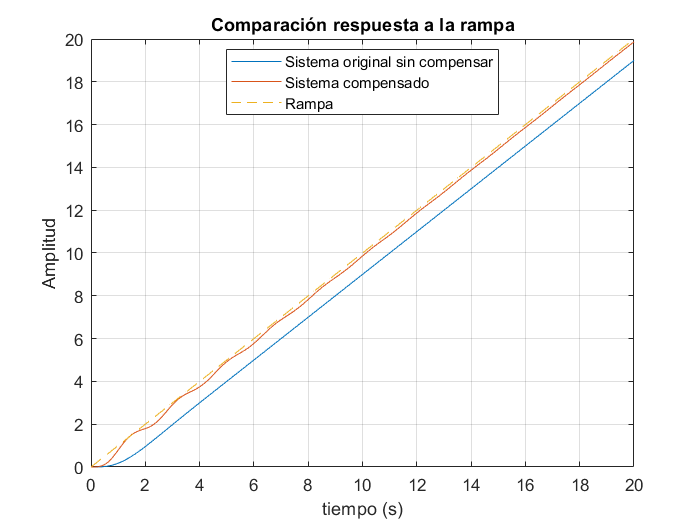

t=0:0.1:20;
r=tf(1,[1 0]);
fsys_r=r*feedback(G,1);
fsysC1_r=r*feedback(sysC,1);
a=step(fsys_r,t);
b=step(fsysC1_r,t);
plot(t,a,t,b,t,t,'--')
legend('Sistema original sin compensar','Sistema compensado','Rampa','location','best');
title('Comparación respuesta a la rampa')
xlabel('tiempo (s)')
ylabel('Amplitud')
grid